clc; clear; close all;

%% FILE PATHS

expFile = "C:\Users\marke\Desktop\university\semester 8\Thesis\experiment\all series (Repaired).xlsx";

cfdFile = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\naca0012_coefficients_summary.csv";

cmeshFile = "\\wsl.localhost\Ubuntu-22.04\home\mteggeri\OpenFOAM\mteggeri-13\run\all_forceCoeffs_raw.dat";

xfoilFiles = [
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_150k_v15"
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_200k_v20"
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_250k_v25"
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_300k_v30"
    "C:\Users\marke\Desktop\XFOIL6.99\naca0012_350k_v35"
];

sheets = ["V=15","V=20","V=25","V=30","V=35"];
velocities = [15 20 25 30 35];   % m/s

%% REYNOLDS PARAMETERS (set to your experiment values)
chord = 0.2;        % chord length (m) — adjust if different
nu = 1.5e-5;        % kinematic viscosity (m^2/s) — adjust if different
Reynolds = velocities .* chord ./ nu;

%% READ DATA

CFD = readtable(cfdFile);

optsC = delimitedTextImportOptions("NumVariables",6);
optsC.Delimiter = {' ','\t'};
optsC.ConsecutiveDelimitersRule = "join";
optsC.VariableNames = {'Velocity','AoA','Iter','CM','CD','CL'};
optsC.VariableTypes = repmat("double",1,6);

CMESH = readtable(cmeshFile, optsC);

%% ERROR FUNCTION

calcError = @(num, exp) abs(num - exp) ./ max(abs(exp)) * 100;

allResults = table();

%% LOOP

for i = 1:length(sheets)

    %% EXPERIMENT
    EXP = readtable(expFile, 'Sheet', sheets(i));
    AoA_exp = EXP.AoA;
    CL_exp  = EXP.CL;
    CD_exp  = EXP.CD;
    CM_exp  = EXP.CM;

    %% XFOIL
    XF = readmatrix(xfoilFiles(i));
    AoA_xf = XF(:,1);

    CL_xfoil = interp1(AoA_xf, XF(:,2), AoA_exp, 'linear', NaN);
    CD_xfoil = interp1(AoA_xf, XF(:,3), AoA_exp, 'linear', NaN);
    CM_xfoil = interp1(AoA_xf, XF(:,5), AoA_exp, 'linear', NaN);

    %% CFD
    % Assume CFD table has a velocity column named 'Velocity' (m/s).
    % If it has a different name, change 'Velocity' accordingly.
    if any(strcmpi(CFD.Properties.VariableNames,'Velocity'))
        velColName = 'Velocity';
    else
        % fallback: pick the numeric column most likely velocity
        numericCols = varfun(@isnumeric, CFD, 'OutputFormat','uniform');
        velIdx = find(numericCols,1);
        velColName = CFD.Properties.VariableNames{velIdx};
    end

    CFD_i = CFD(abs(CFD.(velColName) - velocities(i)) < 1e-6, :);

    if isempty(CFD_i)
        CL_cfd = NaN(size(AoA_exp));
        CD_cfd = NaN(size(AoA_exp));
        CM_cfd = NaN(size(AoA_exp));
    else
        % detect AoA, CL, CD, CM column names (common names)
        vars = lower(CFD_i.Properties.VariableNames);
        idxAoA = find(contains(vars,{'aoa','alpha','aoadeg','aoa_deg'}),1);
        idxCL  = find(contains(vars,{'cl','c_l'}),1);
        idxCD  = find(contains(vars,{'cd','c_d'}),1);
        idxCM  = find(contains(vars,{'cm','c_m','moment'}),1);

        if isempty(idxAoA); idxAoA = 1; end
        if isempty(idxCL);  CL_cfd = NaN(size(AoA_exp)); end
        if isempty(idxCD);  CD_cfd = NaN(size(AoA_exp)); end
        if isempty(idxCM);  CM_cfd = NaN(size(AoA_exp)); end

        AoA_cfd_raw = CFD_i{:, idxAoA};
        [AoA_cfd, idxSort] = sort(AoA_cfd_raw);
        if ~exist('CL_cfd','var') || all(isnan(CL_cfd))
            try CL_cfd = interp1(AoA_cfd, CFD_i{idxSort, idxCL}, AoA_exp, 'linear', NaN); end
        else
            CL_cfd = interp1(AoA_cfd, CFD_i{idxSort, idxCL}, AoA_exp, 'linear', NaN);
        end
        CD_cfd = interp1(AoA_cfd, CFD_i{idxSort, idxCD}, AoA_exp, 'linear', NaN);
        CM_cfd = interp1(AoA_cfd, CFD_i{idxSort, idxCM}, AoA_exp, 'linear', NaN);
    end

    %% C-MESH
    CMESH_i = CMESH(abs(CMESH.Velocity - velocities(i)) < 1e-6, :);

    if isempty(CMESH_i)
        CL_cmesh = NaN(size(AoA_exp));
        CD_cmesh = NaN(size(AoA_exp));
        CM_cmesh = NaN(size(AoA_exp));
    else
        [AoA_cmesh, idxSort] = sort(CMESH_i.AoA);
        CL_cmesh = interp1(AoA_cmesh, CMESH_i.CL(idxSort), AoA_exp, 'linear', NaN);
        CD_cmesh = interp1(AoA_cmesh, CMESH_i.CD(idxSort), AoA_exp, 'linear', NaN);
        CM_cmesh = interp1(AoA_cmesh, CMESH_i.CM(idxSort), AoA_exp, 'linear', NaN);
    end

    %% ERRORS (ONLY vs EXP)
    err_CL_CFD   = calcError(CL_cfd, CL_exp);
    err_CL_XFOIL = calcError(CL_xfoil, CL_exp);
    err_CL_CMESH = calcError(CL_cmesh, CL_exp);

    err_CD_CFD   = calcError(CD_cfd, CD_exp);
    err_CD_XFOIL = calcError(CD_xfoil, CD_exp);
    err_CD_CMESH = calcError(CD_cmesh, CD_exp);

    err_CM_CFD   = calcError(CM_cfd, CM_exp);
    err_CM_XFOIL = calcError(CM_xfoil, CM_exp);
    err_CM_CMESH = calcError(CM_cmesh, CM_exp);

    %% STORE (store Re instead of velocity)
    results_i = table( ...
        repmat(Reynolds(i), length(AoA_exp), 1), ...
        err_CL_CFD, err_CL_XFOIL, err_CL_CMESH, ...
        err_CD_CFD, err_CD_XFOIL, err_CD_CMESH, ...
        err_CM_CFD, err_CM_XFOIL, err_CM_CMESH, ...
        'VariableNames', { ...
        'Re', ...
        'CL_CFD','CL_XFOIL','CL_CMESH', ...
        'CD_CFD','CD_XFOIL','CD_CMESH', ...
        'CM_CFD','CM_XFOIL','CM_CMESH'} );

    allResults = [allResults; results_i];
end

%% SUMMARY (group by Re)

summary = groupsummary(allResults, "Re", "mean");

disp(summary);

        Re        GroupCount    mean_CL_CFD    mean_CL_XFOIL    mean_CL_CMESH    mean_CD_CFD    mean_CD_XFOIL    mean_CD_CMESH    mean_CM_CFD    mean_CM_XFOIL    mean_CM_CMESH
    __________    __________    ___________    _____________    _____________    ___________    _____________    _____________    ___________    _____________    _____________

         2e+05        14           33.69          15.002           22.768          29.552          26.561           27.939           56.79          65.561           61.024    
    2.6667e+05        14          35.296          12.129           20.774          27.708        

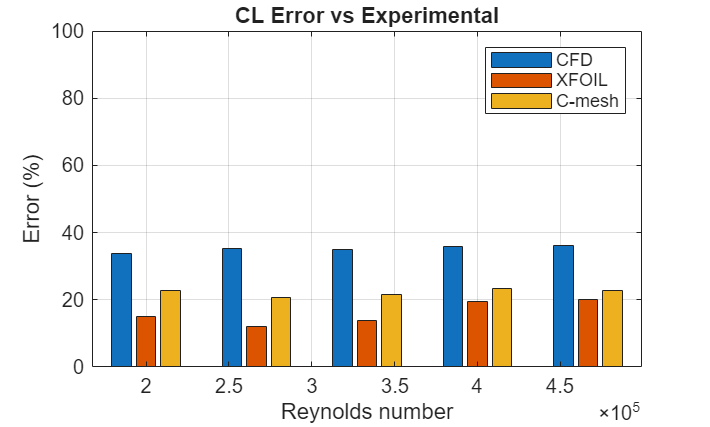


%% PLOTS (x-axis = Reynolds number)

figure;
bar(summary.Re, [summary.mean_CL_CFD summary.mean_CL_XFOIL summary.mean_CL_CMESH]);
title('CL Error vs Experimental');
xlabel('Reynolds number'); ylabel('Error (%)');
legend('CFD','XFOIL','C-mesh'); grid on;
ylim([0 100]);

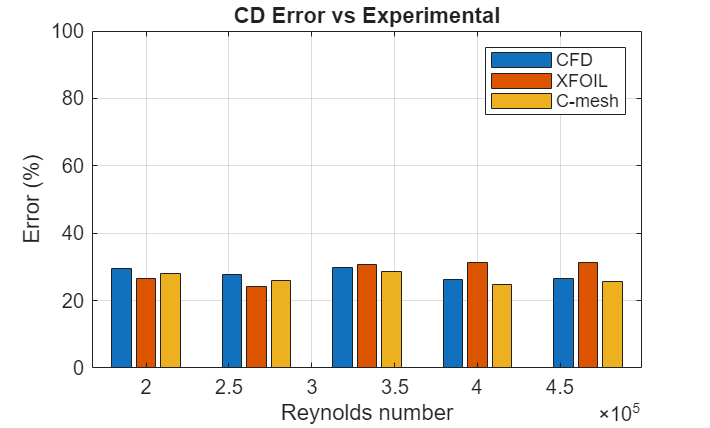


figure;
bar(summary.Re, [summary.mean_CD_CFD summary.mean_CD_XFOIL summary.mean_CD_CMESH]);
title('CD Error vs Experimental');
xlabel('Reynolds number'); ylabel('Error (%)');
legend('CFD','XFOIL','C-mesh'); grid on;
ylim([0 100]);

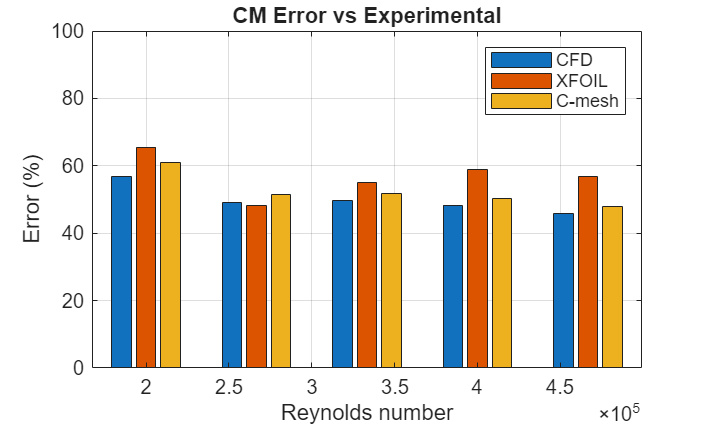


figure;
bar(summary.Re, [summary.mean_CM_CFD summary.mean_CM_XFOIL summary.mean_CM_CMESH]);
title('CM Error vs Experimental');
xlabel('Reynolds number'); ylabel('Error (%)');
legend('CFD','XFOIL','C-mesh'); grid on;
ylim([0 100]);